clc; clear; close all;

v = [17.0596 16.7106 18.2688 17.6981 19.1566];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5659/2 * ones(size(v)) / 1000;

muestras = [1 2 3 4 5];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.9427    0.9226    0.9166    0.8936    0.8891



rho = 1050;

x = eta_sol.^2

x =     0.8888    0.8511    0.8401    0.7985    0.7905


y = rho*v.^2

y = 1.0e+05 *

    3.0558    2.9321    3.5044    3.2888    3.8532


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -648875.1962 * x + 873710.1144


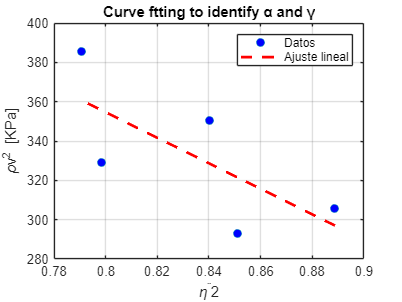


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 8.7371e+05

gamma = -m

gamma = 6.4888e+05


stress = alpha - gamma

stress = 2.2483e+05

strain = -1 + (alpha/gamma)^(1/3)

strain = 0.1043

young = stress/strain

young = 2.1566e+06